clear; clc;
mFile = '../mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);

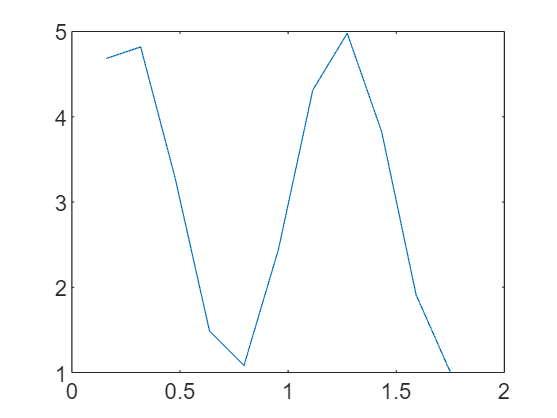

ans =   33.8224 + 0.0000i   0.5293 + 2.4756i   3.4233 -10.0372i   1.7522 - 1.9982i   1.5918 - 0.8714i   1.5484 - 0.2589i   1.5484 + 0.2589i   1.5918 + 0.8714i   1.7522 + 1.9982i   3.4233 +10.0372i   0.5293 - 2.4756i


ans =    3.0748 + 0.0000i   0.0962 + 0.4501i   0.6224 - 1.8249i   0.3186 - 0.3633i   0.2894 - 0.1584i   0.2815 - 0.0471i   0.2815 + 0.0471i


ans =     3.0748    0.4603    1.9282    0.4832    0.3299    0.2854    0.2854



% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);



% Calculate the FFT 
fftx = fft(x, [], 2);
% Calculate normalized magnitude and angle
[mag, ang, frq] = freqMag(fftx);


% Calculate the Energy Spectrum of fftx
eSpec = mag.^2; 
% Get the indices of the most important frequencies
[eSpecs, eSpecr] = sort(eSpec, 2, 'descend');
seSpec = prop(eSpecs, dim=2, cum=true);%cumsum(eSpecs, 2)./(sum(eSpecs, 2)*ones([1 size(eSpecs,2)]));

%imshow(seSpec(1:1000,:))

%surf(seSpec(1:100,:));shading interp

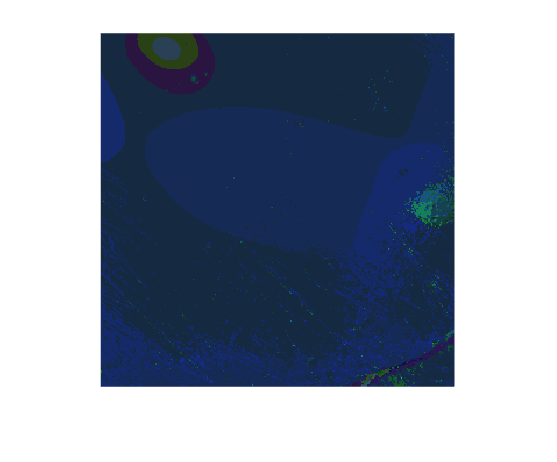

% Use the location of the three top values as color
y=eSpecr(:, 2:4);
y=reshape(y, [h, w, 3]);
mat2img(y);

[~, py]=index2pos(find(seSpec<.95), h*w);

size(unique(eSpecr(:,1:max(py))))

ans =     12     1


% Choosing base frequencies and their energies
bf = unique(eSpecr(:,1:max(py)))

bf =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


beSpec = eSpec(:, bf);

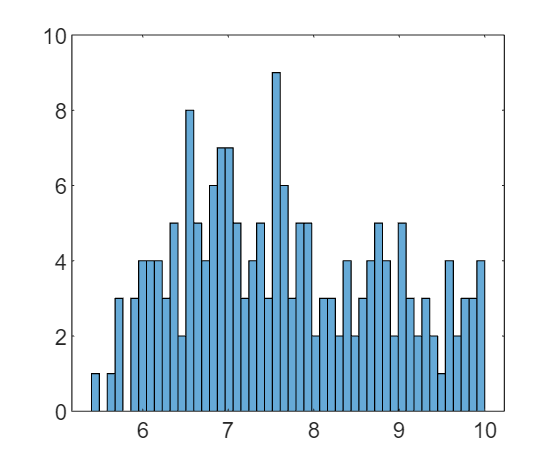

% Finding the limit for filtering values out
ubeSpec = unique(max(beSpec, [], 2));
histogram(ubeSpec(ubeSpec<10), 50)

zlim = 50; % 50 creates smallest # of clusters
%Frequency Signature
beSig =  bin2dec(char(1.*(beSpec>zlim)+'0'));
bin2dec('110000000000') % Mostly Expected

ans = 3072

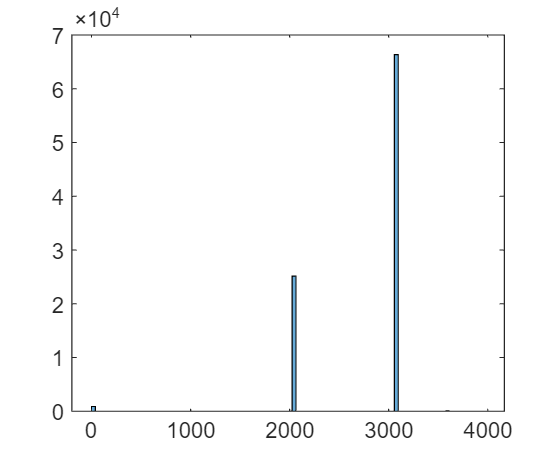

histogram(beSig, 100)

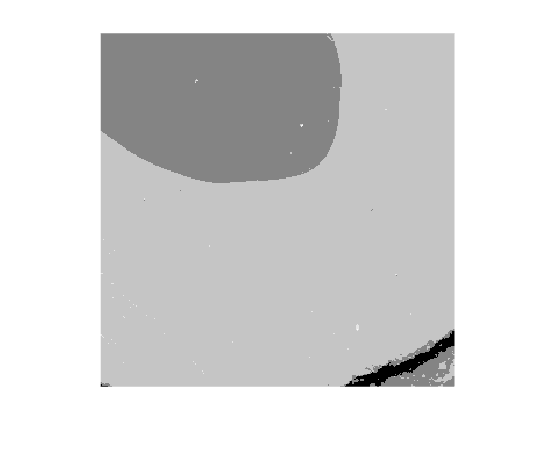

mat2img(reshape(beSig, [h w]));

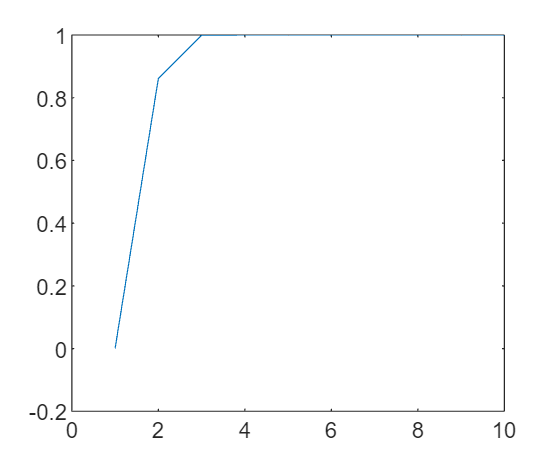

% Clsutering by the frequency signature
K = 10;
rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beSigWinSS] = kmeans(beSig, k);
    sst = sum(sum((beSig-mean(beSig)).^2));
    ssw = sum(beSigWinSS);
    rsqs(k) = 1-ssw/sst;
end
plot(rsqs)

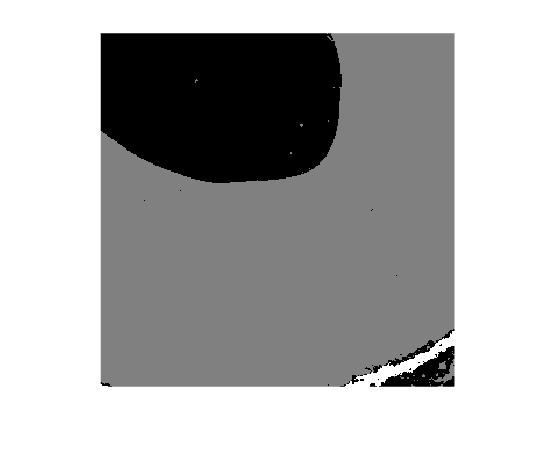

[beSigClusters, beSigCenters, beSigWinSS] = kmeans(beSig, 3);
mat2img(reshape(beSigClusters, [h w]));

% Clsutering by the magnitude
K = 10;
rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beMagWinSS] = kmeans(beSpec, k);
    sst = sum(sum((beSpec-mean(beSpec)).^2));
    ssw = sum(beMagWinSS);
    rsqs(k) = 1-ssw/sst;
end

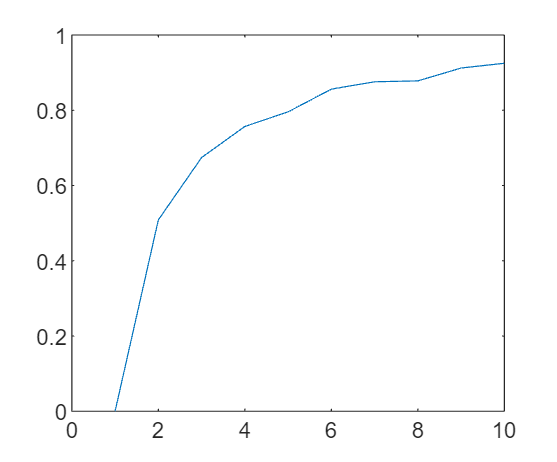

plot(rsqs)

% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beSigCenters, 1) 1]);
for j=1:w*h
    magj = freqMag(fft(x(j, :)));
    magj = bin2dec(char(1.*(magj(bf)>zlim)+'0'));
    ds = sum((beSigCenters-k1s*magj).^2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beSigClusters(j));
end
mean(mcr)

ans = 0.7281

mean(mseC)

ans = 1.3634e+07

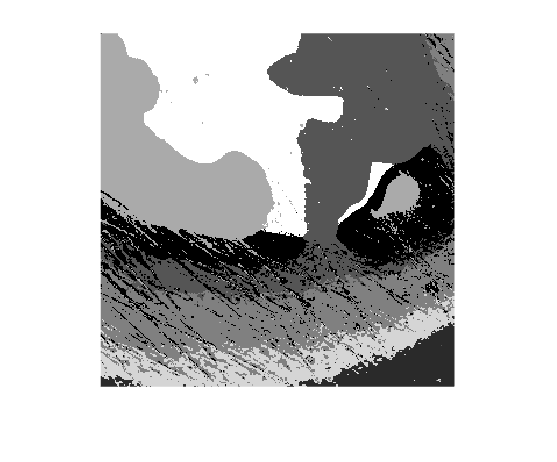

[beMagClusters, beMagCenters, beMagWinSS] = kmeans(beSpec, 7);
mat2img(reshape(beMagClusters, [h w]));

% Clsutering by Scaled Magnitude
K = 10;
rsqs = zeros([K, 1]);
beSpecp = prop(beSpec);
for k=1:K
    [~, ~, beMagWinSS] = kmeans(beSpecp, k);
    sst = sum(sum((beSpecp-mean(beSpecp)).^2));
    ssw = sum(beMagWinSS);
    rsqs(k) = 1-ssw/sst;
end

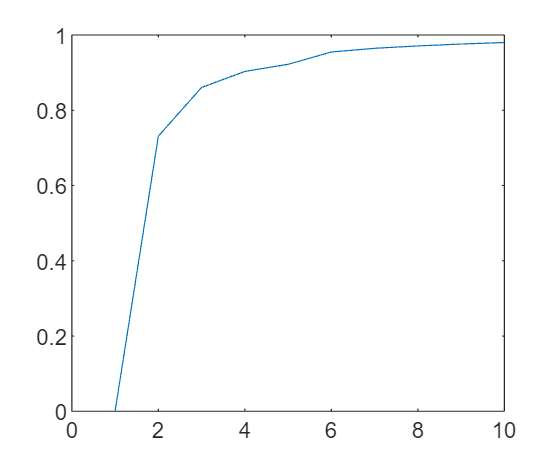

plot(rsqs)

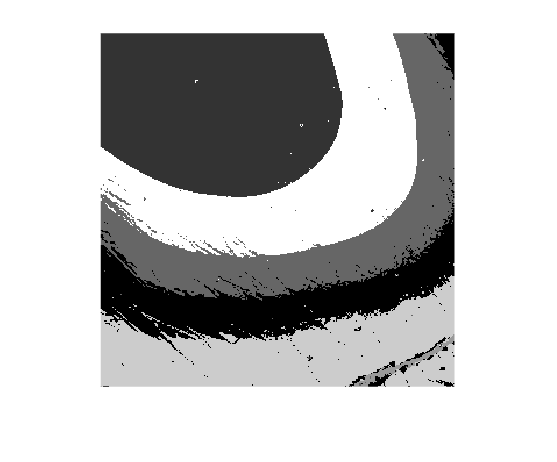

[beMagClusters, beMagCenters, beMagWinSS] = kmeans(beSpecp, 6);
mat2img(reshape(beMagClusters, [h w]));

% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beMagCenters, 1) 1]);
for j=1:w*h
    magj = freqMag(fft(x(j, :)));
    magj = prop(magj(bf));
    ds = sum((beMagCenters-k1s*magj).^2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beMagClusters(j));
end
mean(mcr)

ans = 0.9999

mean(mseC)

ans = 4.1795e-05